clear
clf
y = [1; 1; 1;];
evalues = zeros(10,1);
result = zeros(10,1);

for k = 0:9
    % Setup
    e = 10^(-k);
    evalues(k+1) = e;
    X = [1 1; e 0; 0 e];

    % QR
    [Q, R] = qr(X, 0);
    beta1 = R\(Q'*y);

    % NE
    C = X' * X;
    beta2 = C\(X'*y);

    result(k+1) = norm(beta1 - beta2);
end

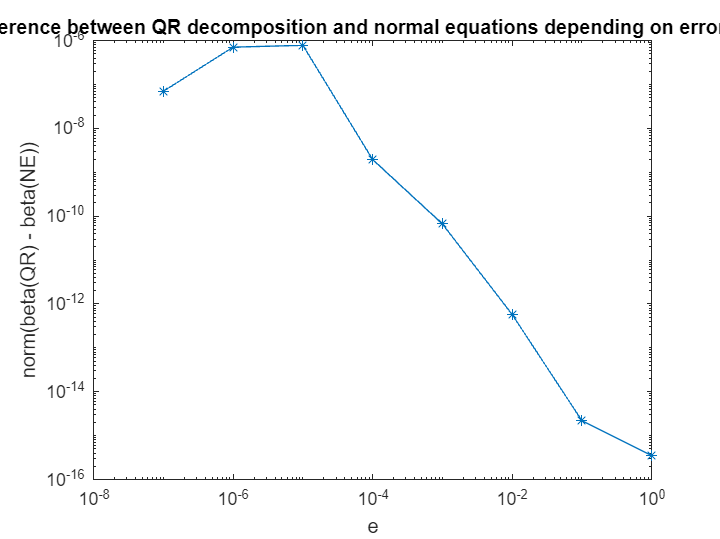

loglog(evalues, result, '-*');
title('Difference between QR decomposition and normal equations depending on error value')
xlabel('e')
ylabel('norm(beta(QR) - beta(NE))')

hold off

clf

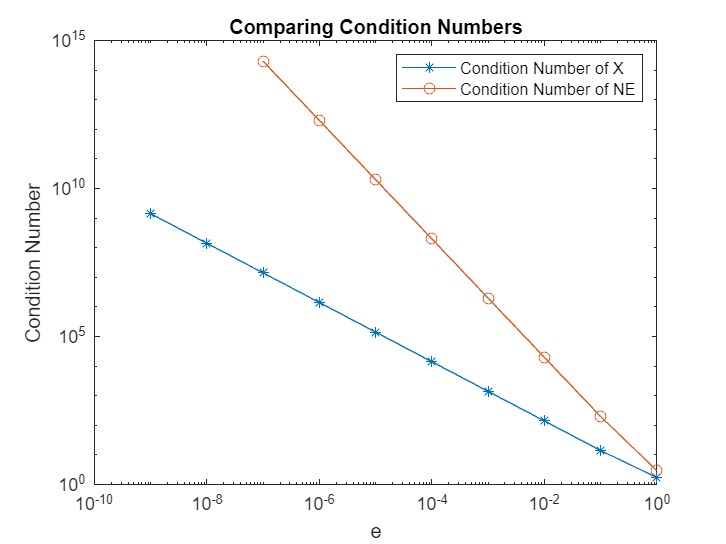

evalues = zeros(16,1);
condXarray = zeros(16,1);
condNEarray = zeros(16,1);

for k = 0:9
    % Setup
    e = 10^(-k);
    evalues(k+1) = e;
    X = [1 1; e 0; 0 e];

    % Calculate condition numbers
    condX = cond(X);
    condNE = cond(X' * X);
    condXarray(k+1) = condX;
    condNEarray(k+1) = condNE;
end

% Plot the condition numbers
loglog(evalues, condXarray, '-*')
hold on
loglog(evalues, condNEarray, '-o');
title('Comparing Condition Numbers')
xlabel('e')
ylabel('Condition Number')
legend('Condition Number of X', 'Condition Number of NE')